# Sample 10-4

## 冗長変換

$\ell_2$ -ノルム最小化

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Redundant transforms

$\ell_2$ -norm minimization

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 非線形近似の設定

(Settings of non-linear approximation)

% # of Coefs.
K = 32;

### 入力信号の生成

(Generation of input sequence)

% # of input samples
nSamples = 128;

% Random process in AR(1) model
rng('default'); 
w = 0.1*randn(nSamples,1);
u = filter(1,[1 -0.95],w);

### 合成辞書

(Synthesis dictionary)

% Synthesis filters
f0 = [  1 1 ]/2;
f1 = [ -1 1 ]/2;

% (Circular) convolution matrix
nF = max(length(f0),length(f1));
X = [zeros(nF-1,nSamples-nF+1) eye(nF-1); eye(nSamples)]; % Circular extension matrix
C = [zeros(nSamples,nF-1) eye(nSamples) zeros(nSamples,nF-1)]; % Clipping matrix

% Atoms in (circular) convolution matrix
d0 = C*convmtx(f0.',nSamples+nF-1)*X;
d1 = C*convmtx(f1.',nSamples+1)*X;

辞書 (Dictionary) $\mathbf{D}$

% Dictionary D (Global matrix representation of synthesis filter bank)
D = zeros(nSamples,2*nSamples);
D(:,1:2:end) = d0;
D(:,2:2:end) = d1;
disp(D)

  1 列から 20 列

    0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000    0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.5000    0.5000    0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.5000    0.5000    0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.5000    0.5000    0.5000   -0.5000         0         0         0         0         0         0         0         0  

### $\ell_2$ -ノルム最小化分析処理

(Analysis process with $\ell_2$ -norm minimization)

% Analysis process
s = pinv(D)*u;

## 非線形近似

(Non-linear approximation)

s = s(:);
[~,ix] = sort(abs(s),'descend');
s(ix(K+1:end)) = 0;

近似結果

v = D*s;

 近似誤差

r = u - v;

### グラフ描画

 (Graph plot)

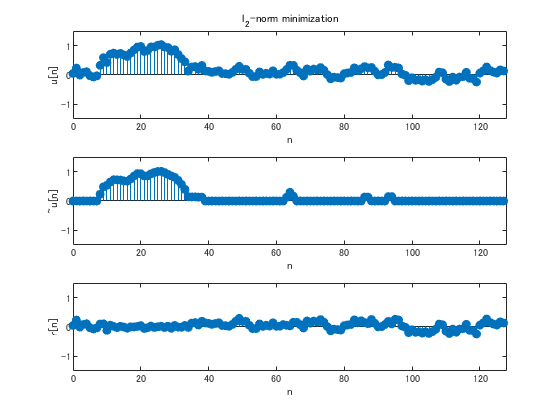

figure(1)

% Input
subplot(3,1,1)
stem(0:nSamples-1,u,'filled')
axis([0 nSamples -1.5 1.5])
xlabel('n')
ylabel('u[n]')
title('l_2-norm minimization')

% NLA
subplot(3,1,2)
stem(0:nSamples-1,v,'filled')
axis([0 nSamples -1.5 1.5])
xlabel('n')
ylabel('~u[n]')

% Residual
subplot(3,1,3)
stem(0:nSamples-1,r,'filled')
axis([0 nSamples -1.5 1.5])
xlabel('n')
ylabel('r[n]')

MSE評価 (MSE evaluation)

mymse = @(x,y) mean((x(:)-y(:)).^2);
fprintf('mse = %f\n',mymse(u,v));

mse = 0.015493


© Copyright, Shogo MURAMATSU, All rights reserved.